clear all
clf
% Bilderna sökväg
imagePath = '../HDR/test2/';
%imagePath = '../HDR/ImagesSmall/';

% Alla tiff-filer i mappen
imageList = dir(fullfile(imagePath, '*.jpg'));
imageAmount = numel(imageList);


%Första bilden
firstImage = imread(fullfile(imagePath, imageList(1).name));

% Hämta storleken på den första bilden
[row, col, channel] = size(firstImage);

%Initialize allImages
allImages = zeros(row, col, channel, imageAmount,'uint8');

%Sparar alla bilder i allImages
for i = 1:imageAmount
    allImages(:,:,:,i) = imread(fullfile(imagePath, imageList(i).name));
    %figure;
    %imshow(allImages(:,:,:,i));
end

%Slumpa pixelpositioner
pixelSamples = 100;

randX = randi([1, row], 1, pixelSamples);
randY = randi([1, col], 1, pixelSamples);

%Skapar Z(i,j) för alla tre kanaler
Z_red = zeros(pixelSamples ,imageAmount);
Z_green = zeros(pixelSamples ,imageAmount);
Z_blue = zeros(pixelSamples ,imageAmount);

for j = 1:imageAmount
    for i =1:pixelSamples 
        Z_red(i,j) = allImages(randX(i), randY(i), 1, j);
        Z_green(i,j) = allImages(randX(i), randY(i), 2, j);
        Z_blue(i,j) = allImages(randX(i), randY(i), 3, j);
    end
end


%B(j)
B = zeros(imageAmount,1);

% lowestExposure = 1/4000;
% B(1) = lowestExposure;
% 
% for j = 2:length(B)
%     B(j) = B(j-1) * 2;
% end

% B(2) = 1/2000; 
% B(3) = 1/1000;
% B(4) = 1/500;
% B(5) = 1/250;
% B(6) = 1/125;
% B(7) = 1/60;
% B(8) = 1/30;
% B(9) = 1/15;
% B(10) = 1/6;
% B(11) = 1/3;
% B(12) = 0.6;
% B(13) = 1.3;

 B(1) = 1/350;
 B(2) = 1/180;
 B(3) = 1/90;

 % B(1) = 1/5;
 % B(2) = 1/2;
 % B(3) = 2;
 % B(4) = 3;

 % B(1) = 1/30;
 % B(2) = 1/6;
 % B(3) = 0.6;


 % B(1) = 1/125;
 % B(2) = 1/3;
 % B(3) = 1.3;

B = log(B);

B =    -5.8579
   -5.1930
   -4.4998


%lambda

lambda = 100;

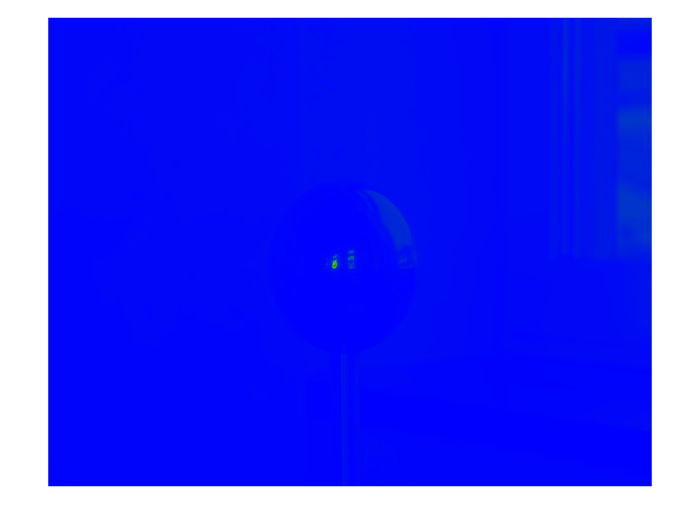

% Skapar den viktade funktionen
w = hat(0:255);
%w = gaussian(0:255);
x = linspace(0,255, 256);

figure;
plot(x,w)

%Beräknar g-kurvan och log(E) med funtionen gsolve
[gCurveRed,lERed] = gsolve(Z_red,B,lambda,w);
[gCurveGreen,lEGreen] = gsolve(Z_green,B,lambda,w);
[gCurveBlue,lEBlue] = gsolve(Z_blue,B,lambda,w);


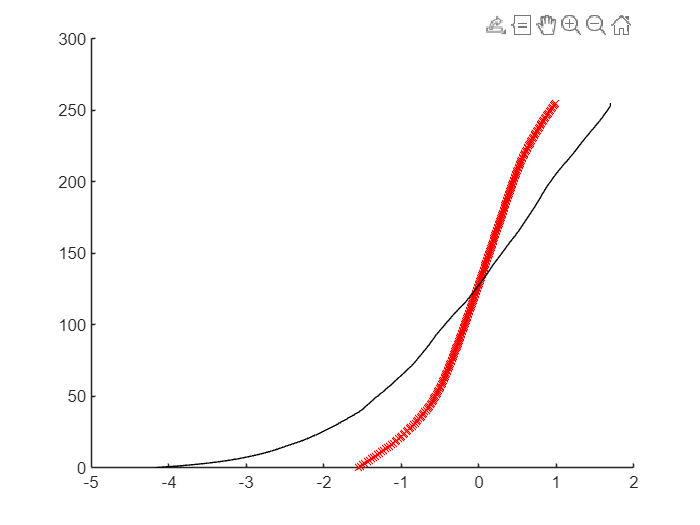


gCurve2 = makegfun;
y = linspace(0, 255, 256)';


figure;
hold on;
plot(gCurveRed, y, 'rx');
plot(gCurve2(:,1), y, 'k'); %Facit

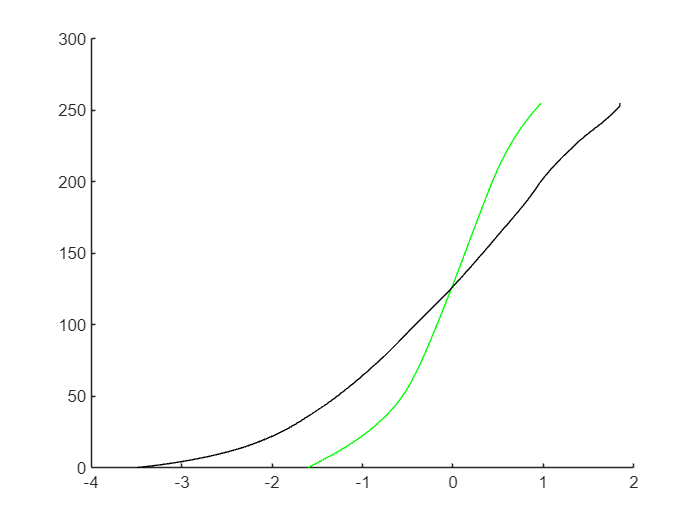


figure;
hold on;
plot(gCurveGreen, y, 'g-');
plot(gCurve2(:,2), y, 'k'); %Facit

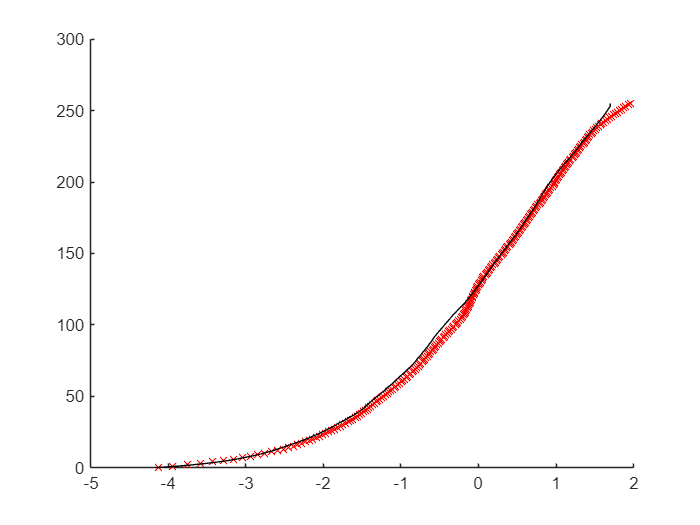


figure;
hold on;
plot(gCurveBlue, y, 'b-');
plot(gCurve2(:,3), y, 'k'); %Facit

allImagesRed = squeeze(allImages(:,:,1,:));
allImagesGreen = squeeze(allImages(:,:,2,:));
allImagesBlue = squeeze(allImages(:,:,3,:));

imRed = createRadianceMap(allImagesRed, gCurveRed, w./127, B);
imGreen = createRadianceMap(allImagesGreen, gCurveGreen, w./127, B);
imBlue = createRadianceMap(allImagesBlue, gCurveBlue, w./127, B);

imRed = exp(imRed);
imGreen = exp(imGreen);
imBlue = exp(imBlue);

%Visa radiance map 
%showRadianceMap(imRed, imGreen, imBlue);

%Skapa HDR bilden genom att lägga ihop kanalerna
HDR = cat(3, imRed, imGreen, imBlue);

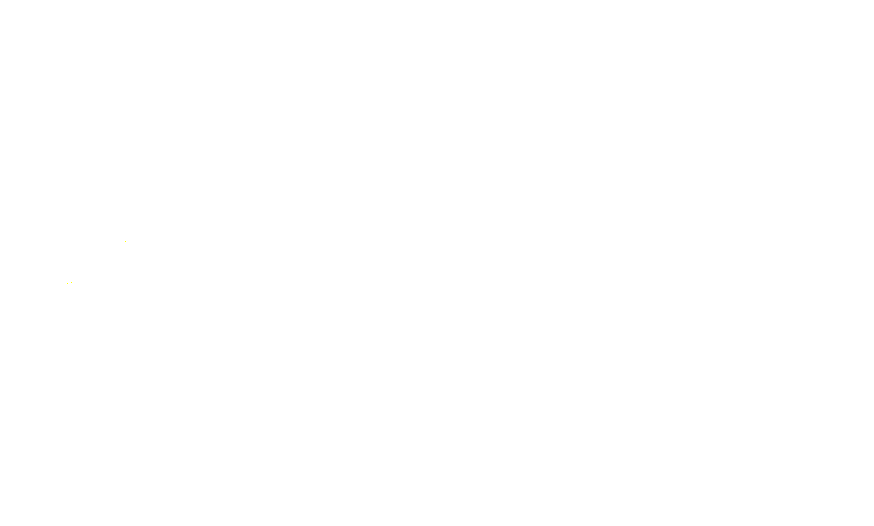

%Tone mapping
imageResult = toneMapping(HDR, true , 'linear', "bilatiral"); %'linear'

figure;
imshow(HDR)


HDRTone = tonemap(HDR);

